# Variational Gradient Matching for Dynamical Systems: Lotka-Volterra

# 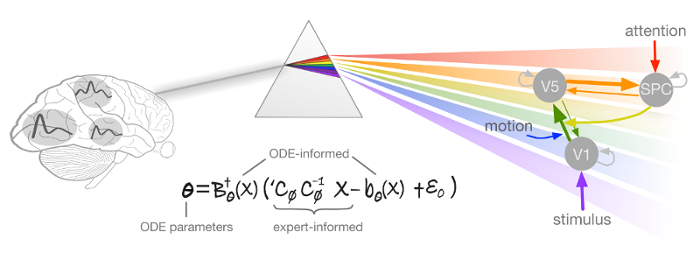.

## **Authors**: 

**Nico Stephan Gorbach** and **Stefan Bauer**, email: nico.gorbach@gmail.com

## Contents:

Instructional code for the NIPS (2018) paper [Scalable Variational Inference for Dynamical Systems](https://papers.nips.cc/paper/7066-scalable-variational-inference-for-dynamical-systems.pdf) by Nico S. Gorbach, Stefan Bauer and Joachim M. Buhmann. Please cite our paper if you use our program for a further publication. The derivations in this document are also given in the doctoral thesis [https://www.research-collection.ethz.ch/handle/20.500.11850/261734](https://www.research-collection.ethz.ch/handle/20.500.11850/261734) as well as in parts of Wenk et al. (2018). 

Example dynamical system used in this code: **Lotka-Volterra** system with **half of the time points** **unobserved**. The ODE parameters are also unobserved.

## User Input: Simulation Settings

- **true ODE parameter**

                Input a row vector of real numbers of size 1 x 4:

        simulation.ode_param = [2,1,4,1];    

- **final time for simulation**

                Input a positive real number:

        simulation.final_time = 2;

- **observation noise**

                Input a function handle:

        simulation.state_obs_variance = @(mean)(bsxfun(@times,[0.5^2,0.5^2],ones(size(mean))));

- **time interval between observations**

                Input a positive real number:

        simulation.interval_between_observations = 0.1;

## User Input: Estimation Settings

- **Kernel Parameters **$\mathbf\phi$

                Input a row vector of positive real numbers of size 1 x 2:

        kernel.param = [10,0.2];  

- **Error variance on state derivatives (i.e.** $\gamma$**)**

                Input a row vector of positive real numbers of size 1 x 2:

        state.derivative_variance = [6,6];

- **Estimation times**

                Input a row vector of positive real numbers in ascending order:

        time.est = 0:0.1:4;        

Preliminary operations

close all; clc; addpath('VGM_functions')

## Preprocessing

[symbols,simulation,ode,odes_path,coupling_idx,opt_settings,plot_settings] = preprocessing_Lotka_Volterra (simulation);

 
ODEs:
 
/ d x_1                                  \
| ----- == theta_1 x_1 - theta_2 x_1 x_2 |
|   dt                                   |
|                                        |
| d x_2                                  |
| ----- == theta_4 x_1 x_2 - theta_3 x_2 |
\   dt                                   /



## Mass Action Dynamical Systems

A deterministic dynamical system is represented by a set of $K$ ordinary differential equations (ODEs) with model parameters $\mathbf\theta \in \mathcal{R}^d$ that describe the evolution of $K$ states $\mathbf{x}(t) = [x_1(t),\ldots, x_K(t)]^T$ such that:  

$\dot{\mathbf{x}}(t) = \frac{d \mathbf{x}(t)}{d t} = \mathbf{f}(\mathbf{x}(t),\mathbf\theta) \qquad (1)$,

A sequence of observations, $\mathbf{y}(t)$, is usually contaminated by measurement error which we assume to be normally distributed with zero mean and variance for each of the $K$ states, i.e. $\mathbf{E}\sim\mathcal{N}(\mathbf{E};\mathbf{0},\mathbf{D})$, with $\mathbf{D}_{ik}=\sigma_k ^2 \delta_{ik}$. For $N$ distinct time points the overall system may therefore be summarized as  

$\mathbf{Y} = \mathbf{X} + \mathbf{E}$,

where

$\mathbf{X} = [\mathbf{x}(t_1),\ldots,\mathbf{x}(t_N)] =  [\mathbf{x}_1,\ldots,\mathbf{x}_K]^T$,

$\mathbf{Y} = [\mathbf{y}(t_1),\ldots,\mathbf{y}(t_N)] =  [\mathbf{y}_1,\ldots,\mathbf{y}_K]^T$,

and $\mathbf{x}_k = [x_k(t_1),\ldots,x_k(t_N)]^T$ is the $k$'th state sequence and $\mathbf{y}_k = [y_k(t_1),\ldots,y_k(t_N)]^T$ are the observations. Given the observations $\mathbf{Y}$ and the description of the dynamical system (1), the aim is to estimate both state variables $\mathbf{X}$ and parameters $\mathbf\theta$.

We consider only dynamical systems that are ***locally linear ***with respect to ODE parameters $\mathbf\theta$ and individual states $\mathbf{x}$. Such ODEs include mass-action kinetics and are given by:

$f_{k}(\mathbf{x}(t),\theta) = \sum_{i=1} \theta_{ki} \prod_{j \in
\mathcal{M}_{ki}} x_j \qquad (2)$,

with $\mathcal{M}_{ki} \subseteq \{ 1, \dots, K\}$describing the state variables in each factor of the equation (i.e. the functions are linear in parameters and contain arbitrary large products of monomials of the states).

## Simulate Trajectories

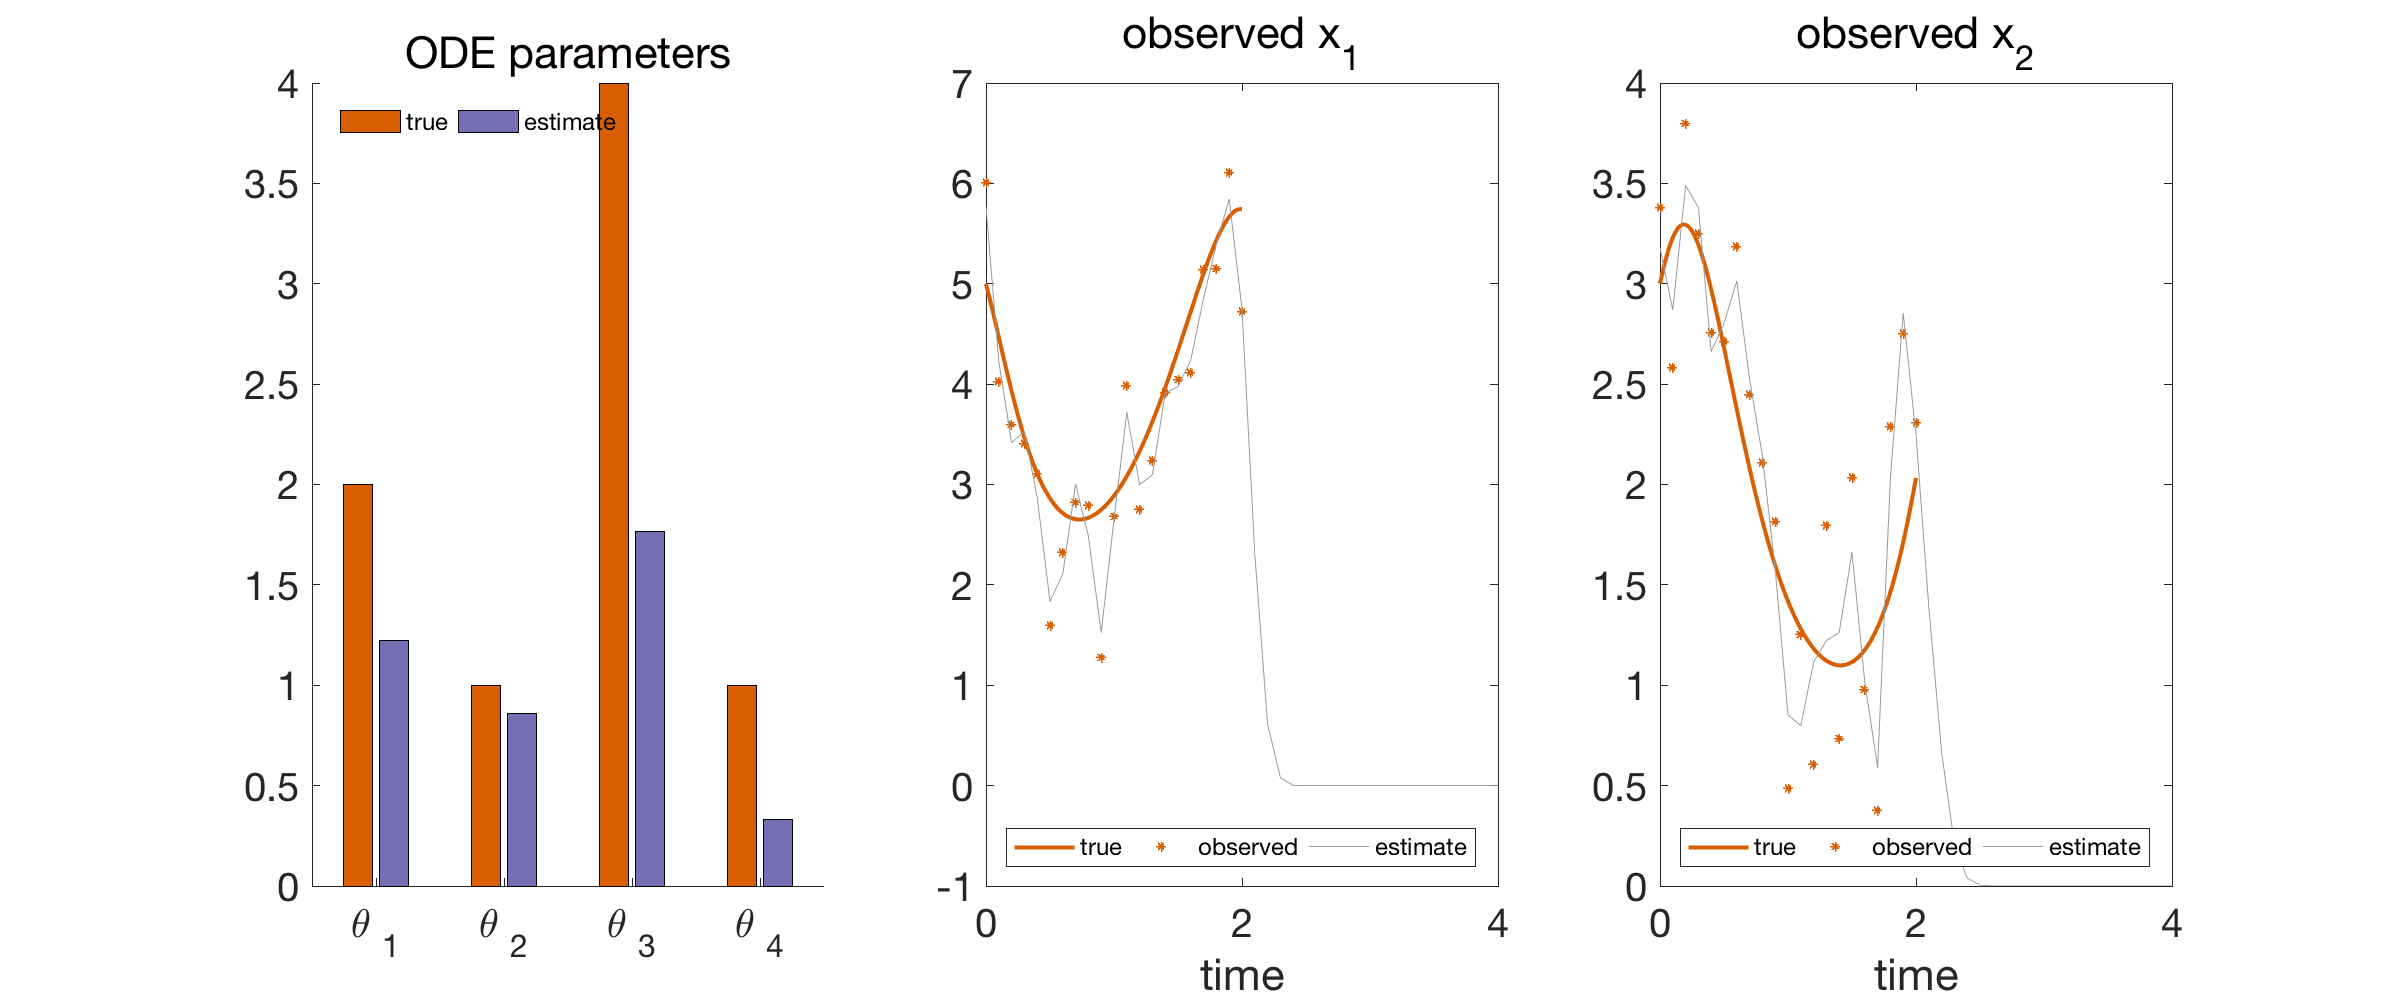

[simulation,obs_to_state_relation,fig_handle,plot_handle] = simulate_state_dynamics(simulation,state,symbols,ode,odes_path,time,plot_settings);

start timer

tic;

## Prior on States and State Derivatives

Gradient matching with Gaussian processes assumes a joint Gaussian process prior on states and their derivatives:

$\left(\begin{array}{c} \mathbf{X} \\ \dot{\mathbf{X}} \end{array}\right)
 \sim \mathcal{N} \left(
\begin{array}{c} \mathbf{X} \\ \dot{\mathbf{X}} \end{array}~;~
\begin{array}{c}
 \mathbf{0} \\
\mathbf{0}
 \end{array}~,~
\begin{array}{cc}
 \mathbf{C}_{\mathbf\phi} & \mathbf{C}_{\mathbf\phi}' \\ '\mathbf{C}_\mathbf{\phi} &
 \mathbf{C}_{\mathbf\phi}'' \end{array} \right) \qquad (3)$,

with         

$\mathrm{cov}(x_k(t), x_k(t)) = C_{\mathbf\phi_k}(t,t')$, 

$\mathrm{cov}(\dot{x}_k(t), x_k(t)) = \frac{\partial C_{\mathbf{\phi}_k}(t,t')
}{\partial t} =: C_{{\mathbf\phi}_k}'(t,t')$, 

$\mathrm{cov}(x_k(t), \dot{x}_k(t)) = \frac{\partial C_{\mathbf\phi_k}(t,t')}{\partial t'} =: {'C_{\mathbf\phi_k}(t,t')}$, 

$\mathrm{cov}(\dot{x}_k(t), \dot{x}_k(t)) = \frac{\partial
C_{\mathbf\phi_k}(t,t') }{\partial t \partial t'} =: C_{\mathbf\phi_k}''(t,t')$.

## Matching Gradients

Given the joint distribution over states and their derivatives (3) as well as the ODEs (2), we therefore have two expressions for the state derivatives:

$\dot{\mathbf{X}} = \mathbf{F} + \mathbf\epsilon_1, \mathbf\epsilon_1 \sim
\mathcal{N}\left(\mathbf\epsilon_1;\mathbf{0}, \mathbf{I}\gamma \right)$,

$\dot{\mathbf{X}} = {'\mathbf{C}_{\mathbf\phi}} \mathbf{C}_{\mathbf\phi}^{-1}
~\mathbf{X} + \mathbf\epsilon_2, \mathbf\epsilon_2 \sim
\mathcal{N}\left(\mathbf\epsilon_2;\mathbf{0}, \mathbf{A} \right)$,

where $\mathbf{F} := \mathbf{f}(\mathbf{X},\mathbf\theta)$ and $\mathbf{A} :=
\mathbf{C}_{\mathbf\phi}'' -  {'\mathbf{C}_{\mathbf\phi}} \mathbf{C}_{\mathbf\phi}^{-1}
\mathbf{C}_{\mathbf\phi}'$ and $\gamma$ is the error variance in the ODEs. Note that, in a deterministic system, the output of the ODEs $\mathbf{F}$ should equal the state derivatives $\dot{\mathbf{X}}$. However, in the first equation above we relax this contraint by adding stochasticity to the state derivatives $\dot{\mathbf{X}}$ in order to compensate for a

potential model mismatch. The second equation above is obtained by deriving the conditional distribution for $\dot{\mathbf{X}}$ from the joint distribution in equation (3). Equating the two expressions in the equations above we can eliminate the unknown state derivatives $\dot{\mathbf{X}$:

$\mathbf{F} = {'\mathbf{C}_{\mathbf\phi}} \mathbf{C}_{\mathbf\phi}^{-1} ~\mathbf{X} +
\mathbf\epsilon_0 \qquad (4)$,

with $\mathbf{\epsilon_0} := \mathbf{\epsilon_2} - \mathbf{\epsilon_1}$.

[dC_times_invC,inv_C,A_plus_gamma_inv] = kernel_function(kernel,state,time.est);

## Rewrite ODEs as Linear Combination in Parameters

Since, according to the mass action dynamics (equation 2), the ODEs are ***linear in the parameters ***$\mathbf\theta$ we can rewrite the ODEs in equation (2) as a linear combination in the parameters:

$\mathbf{B}_{\mathbf{\theta} k} \mathbf{\theta} + \mathbf{b}_{\mathbf{\theta} k} \stackrel{!}{=}
\mathbf{f}_k(\mathbf{X},\mathbf{\theta}) \qquad (5)$,

where matrices $\mathbf{B}_{\mathbf{\theta} k}$ and $\mathbf{b}_{\mathbf{\theta} k}$ and $\mathbf{b}_{\mathbf\theta k}$ are defined such that the ODEs $\mathbf{f}_k(\mathbf{X},\mathbf{\theta})$ are expressed as a linear combination in $\mathbf{\theta}$.

[ode_param.lin_comb.B,ode_param.lin_comb.b] = rewrite_odes_as_linear_combination_in_parameters(ode,symbols);

## Posterior over ODE Parameters

Inserting (5) into (4) and solving for $$\mathbf{\theta}$$ yields:

$\mathbf{\theta} = \mathbf{B}_{\mathbf{\theta}}^+ \left( {'\mathbf{C}_{\mathbf{\phi}}}
\mathbf{C}_{\mathbf{\phi}}^{-1} \mathbf{X} - \mathbf{b}_{\mathbf{\theta}} + \mathbf{\epsilon_0}
\right)$,

where $\mathbf{B}_{\mathbf{\theta}}^+$ denotes the pseudo-inverse of $\mathbf{B}_{\mathbf{\theta}}$. Since $$\mathbf{C}_{\mathbf{\phi}}$$ is block diagonal we can rewrite the expression above as:

$\mathbf{\theta} = \left( \mathbf{B}_{\mathbf{\theta}}^T \mathbf{B}_{\mathbf{\theta}} \right)^{-1} ~
\mathbf{B}_{\mathbf{\theta}}^T  \left( \sum_k {'\mathbf{C}_{\mathbf{\phi}_k}}
\mathbf{C}_{\mathbf{\phi}_k}^{-1} \mathbf{X}_k - \mathbf{b}_{\mathbf{\theta} k} + \mathbf{\epsilon_0}^{(k)} \right)\\ ~
= \left( \mathbf{B}_{\mathbf{\theta}}^T \mathbf{B}_{\mathbf{\theta}} \right)^{-1} \left(
\sum_k \mathbf{B}_{\mathbf{\theta} k}^T \left( {'\mathbf{C}_{\mathbf{\phi}_k}}
\mathbf{C}_{\mathbf{\phi}_k}^{-1} \mathbf{X}_k - \mathbf{b}_{\mathbf{\theta} k} +
\mathbf{\epsilon_0}^{(k)} \right) \right)$,

where we subsitute the Moore-Penrose inverse for the pseudo-inverse (i.e. $\mathbf{B}_{\mathbf{\theta}}^+ := \left( \mathbf{B}_{\mathbf{\theta}}^T \mathbf{B}_{\mathbf{\theta}}
\right)^{-1} \mathbf{B}_{\mathbf{\theta}}^T$). We can therefore derive the posterior distribution over ODE parameters:

$p(\mathbf{\theta} \mid \mathbf{X}, \mathbf{\phi}, \gamma) 
= \mathcal{N}\left(\mathbf{\theta} ; \left( \mathbf{B}_{\mathbf{\theta}}^T
\mathbf{B}_{\mathbf{\theta}} \right)^{-1} \left( \sum_k \mathbf{B}_{\mathbf{\theta} k}^T ~
\left( {'\mathbf{C}_{\mathbf{\phi} k}} \mathbf{C}_{\mathbf{\phi} k}^{-1} \mathbf{X}_k -
\mathbf{b}_{\mathbf{\theta} k} \right) \right), ~ \mathbf{B}_{\mathbf{\theta}}^+ ~
(\mathbf{A} + \mathbf{I}\gamma) ~ \mathbf{B}_{\mathbf{\theta}}^{+T}\right) \qquad (6)$.

## Rewrite ODEs as Linear Combination in Individual States

Since, according to the mass action dynamics (equation 2), the ODEs are ***linear in the individual state*** $\mathbf{x}_u$ we can rewrite the ODE $\mathbf{f}_k(\mathbf{X},\mathbf\theta)$ as a linear combination in the individual state $\mathbf{x}_u$:

$\mathbf{R}_{uk} \mathbf{x}_u + \mathbf{r}_{uk} \stackrel{!}{=}
\mathbf{f}_k(\mathbf{X},\mathbf{\theta})$,

where matrices $ \mathbf{R}_{uk}$ and  $\mathbf{r}_{uk}$ are defined such that the ODE $\mathbf{f}_k(\mathbf{X},\mathbf{\theta})$ is expressed as a linear combination in the individual state $\mathbf{x}_u$.

[state.lin_comb.R,state.lin_comb.r] = rewrite_odes_as_linear_combination_in_ind_states(ode,symbols,coupling_idx.states);

## Posterior over Individual States

Given the linear combination of the ODEs w.r.t. an individual state, we define the matrices $\mathbf{B}_u$ and $\mathbf{b}_u$ such that the expression $$\mathbf{f}(\mathbf{X},\mathbf{\theta}) - {'\mathbf{C}}_{\mathbf{\phi}}
\mathbf{C}_{\mathbf{\phi}}^{-1} \mathbf{X}$$ is rewritten as a linear combination in an individual state $\mathbf{x}_u$:

$\mathbf{B}_{u} \mathbf{x}_u + \mathbf{b}_{u} \stackrel{!}{=}
\mathbf{f}(\mathbf{X},\mathbf{\theta}) - {'\mathbf{C}}_{\mathbf{\phi}}
\mathbf{C}_{\mathbf{\phi}}^{-1} \mathbf{X} \qquad (7)$.

Inserting (7) into (4) and solving for $$\mathbf{x}_u$$ yields:

$$\mathbf{x}_u = \mathbf{B}_{u}^+ \left( \mathbf{\epsilon_0} -\mathbf{b}_{u}
\right)$$,

where $$\mathbf{B}_{u}^+$$ denotes the pseudo-inverse of $$\mathbf{B}_{u}$$. Since $$\mathbf{C}_{\mathbf{\phi}}$$ is block diagonal we can rewrite the expression above as:

$\mathbf{x}_u = \left( \mathbf{B}_{u} \mathbf{B}_{u}^T \right)^{-1}
\mathbf{B}_{u}^T \sum_k \left(\mathbf{\epsilon_0}^{(k)} -\mathbf{b}_{uk} \right)\\ \quad
= \left( \mathbf{B}_{u} \mathbf{B}_{u}^T \right)^{-1} \sum_k
\mathbf{B}_{uk}^T \left(\mathbf{\epsilon_0}^{(k)} -\mathbf{b}_{uk} \right)$,

where we subsitute the Moore-Penrose inverse for the pseudo-inverse (i.e. $\mathbf{B}_{\mathbf{\theta}}^+ := \left( \mathbf{B}_{\mathbf{\theta}}^T \mathbf{B}_{\mathbf{\theta}}
\right)^{-1} \mathbf{B}_{\mathbf{\theta}}^T$).  We can therefore derive the posterior distribution over an individual state $$\mathbf{x}_{u}$$:

$p(\mathbf{x}_u \mid \mathbf{X}_{-u}, \mathbf{\phi}, \gamma)
= \mathcal{N}\left(\mathbf{x}_u ; \left( \mathbf{B}_{u} \mathbf{B}_{u}^T
\right)^{-1} \left( - \sum_k \mathbf{B}_{uk}^T \mathbf{b}_{uk} \right),
~\mathbf{B}_{u}^{+} ~ (\mathbf{A} + \mathbf{I}\gamma) ~ \mathbf{B}_u^{+T}
\right) \qquad (8)$,

with $$\mathbf{X}_{-u}$$ denoting the set of all states except state $$\mathbf{x}_u$$. 

## Mean-field Variational Inference

To infer the parameters $$\mathbf{\theta}$$, we want to find the maximum a posteriori estimate (MAP):

$\mathbf{\theta}^* := \mathrm{arg} \max_{\mathbf{\theta}} ~ \ln p(\mathbf{\theta} \mid
\mathbf{Y},\mathbf{\phi},\gamma,\mathbf \sigma)\\ \quad
= \mathrm{arg}\max_{\mathbf{\theta}} ~ \ln \int  p(\mathbf{\theta},\mathbf{X} \mid
\mathbf{Y},\mathbf{\phi},\gamma,\mathbf\sigma) d\mathbf{X}\\ \quad
= \mathrm{arg}\max_{\mathbf{\theta}} ~ \ln \int p(\mathbf{\theta} \mid \mathbf{X},\mathbf{\phi},\gamma)
p(\mathbf{X} \mid \mathbf{Y}, \mathbf{\phi},\mathbf\sigma) d\mathbf{X} \qquad
(9)$.

However, the integral above is intractable due to the strong couplings induced by the nonlinear ODEs $$\mathbf{f}$$ which appear in the term $$p(\mathbf{\theta} \mid \mathbf{X},\mathbf{\phi},\gamma)$$.

We use mean-field variational inference to establish variational lower bounds that are analytically tractable by decoupling state variables from the ODE parameters as well as decoupling the state variables from each other. Note that, since the ODEs described by equation (2) are ***locally linear***, both conditional distributions $$p(\mathbf{\theta} \mid
\mathbf{X},\mathbf{Y},\mathbf{\phi},\gamma,\mathbf\sigma)$$ (equation (6)) and $$p(\mathbf{x}_u \mid \mathbf{\theta},
\mathbf{X}_{-u},\mathbf{Y},\mathbf{\phi},\gamma,\mathbf\sigma)$$ (equation (8)) are analytically tractable and Gaussian distributed as mentioned previously. The decoupling is induced by designing a variational distribution $$Q(\mathbf{\theta},\mathbf{X})$$ which is restricted to the family of factorial distributions:

$$\mathcal{Q} := \bigg{\{} Q : Q(\mathbf{\theta},\mathbf{X}) = q(\mathbf{\theta}) \prod_u
q(\mathbf{x}_u) \bigg{\}}$$.

The particular form of $$q(\mathbf{\theta})$$ and $$q(\mathbf{x}_u)$$ are designed to be Gaussian distributed which places them in the same family as the true full conditional distributions. To find the optimal factorial distribution we minimize the Kullback-Leibler divergence between the variational and the true posterior distribution:

$$\hat{Q} := \mathrm{arg} \min_{Q(\mathbf{\theta},\mathbf{X}) \in \mathcal{Q}} \mathrm{KL}
\left[ Q(\mathbf{\theta},\mathbf{X}) \mid \mid p(\mathbf{\theta},\mathbf{X} \mid
\mathbf{Y},\mathbf{\phi}, \gamma,\mathbf\mathbf{\sigma}) \right] \qquad (10)$$,

where $$\hat{Q}$$ is the proxy distribution. The proxy distribution that minimizes the KL-divergence (10) depends on the true full conditionals and is given by:

$\hat{q}({\mathbf{\theta}}) \propto \exp \left(~ E_{Q_{-\mathbf{\theta}}} \ln p(\mathbf{\theta} \mid
\mathbf{X},\mathbf{Y},\mathbf{\phi},\gamma,\mathbf\mathbf{\sigma}) ~\right) \qquad (11)\\
\hat{q}(\mathbf{x}_u) \propto \exp\left( ~ E_{Q_{-u}} \ln p(\mathbf{x}_u
\mid \mathbf{\theta}, \mathbf{X}_{-u},\mathbf{Y},\mathbf{\phi},\gamma,\mathbf{\sigma}) ~ \right)
\qquad (12)$.

## Fitting observations of state trajectories

We fit the observations of state trajectories by standard GP regression. The data-informed distribution$ $p(\mathbf{X} \mid \mathbf{Y}, \mathbf{\phi},\mathbf\mathbf{\sigma})$$ in euqation (9) can be determined analytically using Gaussian process regression with the GP prior $$p(\mathbf{X} \mid
\mathbf{\phi}) = \prod_k \mathcal{N}(\mathbf{x}_k ;
\mathbf{0},\mathbf{C}_{\mathbf{\phi}_k})$$:

$$p(\mathbf{X} \mid \mathbf{Y}, \mathbf{\phi},\gamma) = \prod_k
\mathcal{N}(\mathbf{x}_k ;
\mathbf\mu_k(\mathbf{y}_k),\mathbf\mathbf{\sigma}_k)$$,

where $$\mathbf\mu_k(\mathbf{y}_k) := \mathbf{\sigma}_k^{-2} \left(\mathbf{\sigma}_k^{-2}
\mathbf{I} + \mathbf{C}_{\mathbf{\phi}_k}^{-1} \right)^{-1} \mathbf{y}_k$$ and $$\mathbf{\sigma}_k ^{-1}:=\mathbf{\sigma}_k^{-2} \mathbf{I} +
\mathbf{C}_{\mathbf\mathbf{\phi}_k}^{-1}$$.

[mu,inv_sigma] = fitting_state_observations(inv_C,obs_to_state_relation,simulation,symbols);

## Coordinate Ascent Variational Gradient Matching

We minimize the KL-divergence in equation (10) by coordinate descent (where each step is analytically tractable) by iterating between determining the proxy for the distribution over ODE parameters $$\hat{q}(\mathbf{\theta})$$ and the proxies for the distribution over individual states $$\hat{q}(\mathbf{x}_u)$$.

- **Initialize the state estimation by the GP regression posterior**

            state.proxy.mean = array2table([time.est',mu],'VariableNames',['time',symbols.state_string]);

- **Coordinate ascent**

            for i = 1:opt_settings.coord_ascent_numb_iter

- **Proxy for ODE parameters**

                    Expanding the proxy distribution in equation (11) for $$\mathbf{\theta}$$ yields:

                           $\hat{q}(\mathbf{\mathbf\theta}) \propto \exp \left( ~E_{Q_{-\mathbf\theta}}
     \ln p(\mathbf\theta \mid \mathbf{X},\mathbf{Y},\mathbf\phi,\gamma,\mathbf\sigma) ~
     \right) \\ \qquad
= \exp \left( ~E_{Q_{-\mathbf{\theta}}} \ln \mathcal{N}\left(\mathbf{\theta} ; \left(
    \mathbf{B}_{\mathbf{\theta}}^T \mathbf{B}_{\mathbf{\theta}} \right)^{-1} \left( \sum_k
    \mathbf{B}_{\mathbf{\theta} k}^T ~ \left( {'\mathbf{C}_{\mathbf{\phi} k}}
    \mathbf{C}_{\mathbf{\phi} k}^{-1} \mathbf{X}_k - \mathbf{b}_{\mathbf{\theta} k} \right)
    \right), ~ \mathbf{B}_{\mathbf{\theta}}^+ ~ (\mathbf{A} + \mathbf{I}\gamma) ~
    \mathbf{B}_{\mathbf{\theta}}^{+T} \right) ~\right)$,

                    where we substitute $$p(\mathbf{\theta} \mid \mathbf{X},\mathbf{\phi},\gamma)$$ with its density given in equation (6).

             [param_proxy_mean,param_proxy_inv_cov] = proxy_for_ode_parameters(state.proxy.mean{:,symbols.state_string},...
                    dC_times_invC,ode_param.lin_comb,symbols,A_plus_gamma_inv,opt_settings);

Intermediate results

            if i==1 || ~mod(i,1)
                plot_results(fig_handle,state.proxy,simulation,param_proxy_mean,plot_handle,symbols,plot_settings,'not_final');
            end           

- **Proxy for individual states**

                Expanding the proxy distribution in equation (12) over the individual state $$\mathbf{x}_u$$:

                $\hat{q}(\mathbf{x}_u) \stackrel{(a)}{\propto} \exp \left( ~ E_{Q_{-u}}  \ln ( p(\mathbf{x}_u \mid \mathbf\theta, \mathbf{X}_{-u},\mathbf\phi,\gamma) p(\mathbf{x}_u  \mid\mathbf{Y},\mathbf\phi,\mathbf\sigma) ) ~ \right)\\ \qquad ~
 \stackrel{(b)}{=} \exp\big( ~ E_{Q_{-u}} \ln
     \mathcal{N}\left(\mathbf{x}_u ; -\mathbf{B}_{u}^+ \mathbf{b}_u,
     ~\mathbf{B}_u^{+} ~ (\mathbf{A} + \mathbf{I}\gamma) ~
     \mathbf{B}_u^{+T} \right) + E_{Q_{-u}} \ln
    \mathcal{N}\left(\mathbf{x}_u ; \mathbf\mu_u(\mathbf{Y}), \mathbf\Sigma_u
    \right) \big)\\ \qquad ~
= \exp\big( ~ E_{Q_{-u}} \ln
                \mathcal{N}\left(\mathbf{x}_u ; -\mathbf{B}_{u}^+ \mathbf{b}_u,
                ~\mathbf{B}_u^{+} ~ (\mathbf{A} + \mathbf{I}\gamma) ~
                \mathbf{B}_u^{+T} \right) + E_{Q_{-u}} \ln
                \mathcal{N}\left(\mathbf{x}_u ; \mathbf\mu_u(\mathbf{Y}), \mathbf{\sigma}_u
                \right) \big)$.

                In (a) we decompose the full conditional nto an ODE-informed distribution and a data-informed distribution and in (b) we substitute the ODE-informed distribution $p(\mathbf{x}_u \mid \mathbf\theta, \mathbf{X}_{-u},\mathbf\phi,\gamma)$ with its density given by equation (8).

            [state.proxy.mean{:,symbols.state_string},state.proxy.inv_cov] = proxy_for_ind_states(state.lin_comb,...
                state.proxy.mean{:,symbols.state_string},param_proxy_mean',dC_times_invC,coupling_idx.states,symbols,mu,...
                inv_sigma,simulation.observed_states,A_plus_gamma_inv,opt_settings);

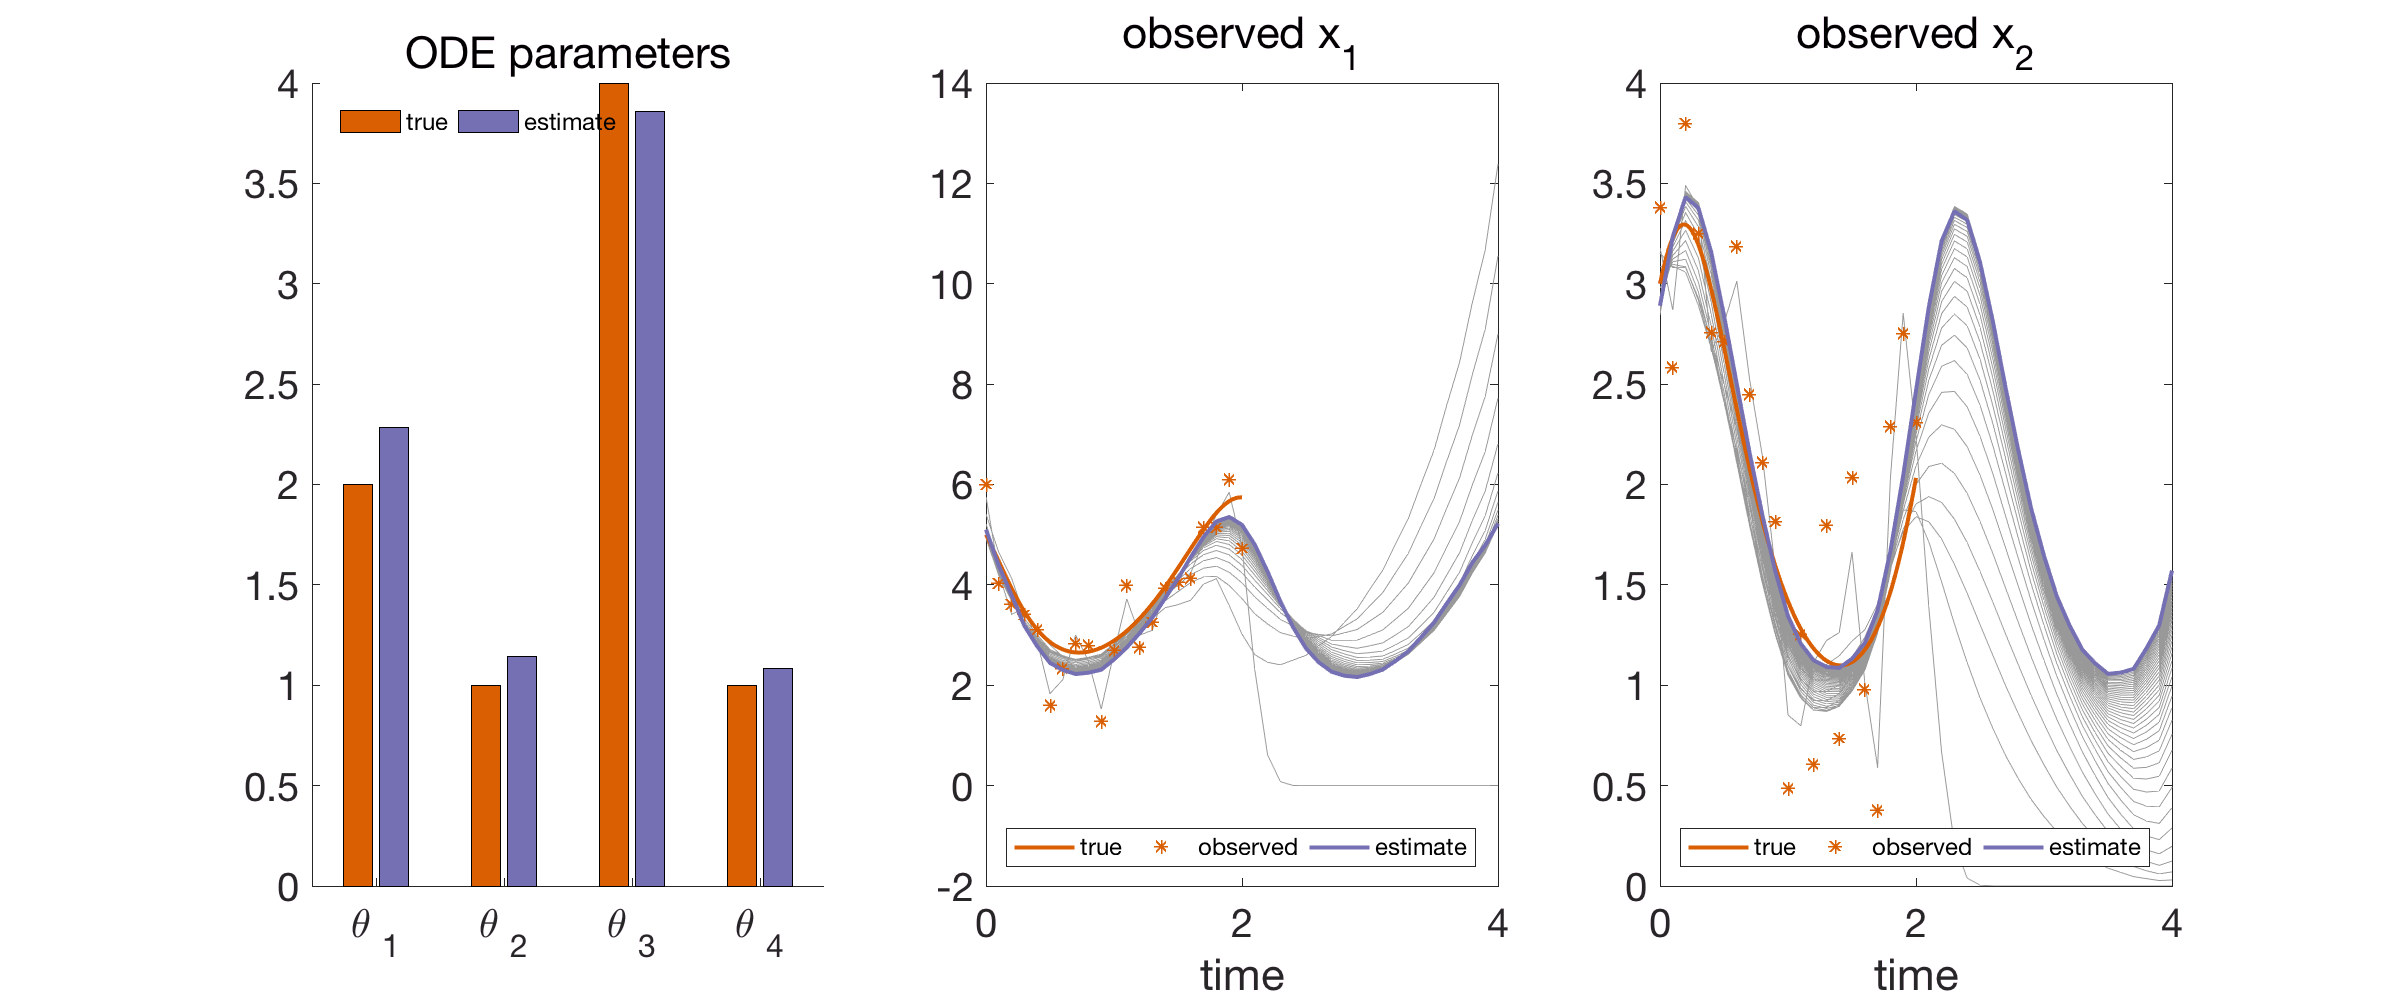

end

Final results

            plot_results(fig_handle,state.proxy,simulation,param_proxy_mean,plot_handle,symbols,plot_settings,'final');

## Time Taken

disp(['time taken: ' num2str(toc) ' seconds'])

time taken: 15.7197 seconds


## References

Gorbach, N.S.  Validation and Inference of Structural Connectivity and Neural Dynamics with MRI data. 2018. ETH Zürich Doctoral Thesis. [https://www.research-collection.ethz.ch/handle/20.500.11850/261734](https://www.research-collection.ethz.ch/handle/20.500.11850/261734). 

**Gorbach, N.S. , Bauer, S. **and Buhmann, J.M., Scalable Variational Inference for Dynamical Systems. 2017a. Neural Information Processing Systems (NIPS). Link to NIPS paper [here](https://papers.nips.cc/paper/7066-scalable-variational-inference-for-dynamical-systems.pdf) and arxiv paper [here](https://arxiv.org/abs/1705.07079).

**Bauer, S. , Gorbach, N.S.** and Buhmann, J.M., Efficient and Flexible Inference for Stochastic Differential Equations. 2017b. Neural Information Processing Systems (NIPS). Link to NIPS paper [here](https://papers.nips.cc/paper/7274-efficient-and-flexible-inference-for-stochastic-systems.pdf).

Wenk, P., Gotovos, A., Bauer, S., Gorbach, N.S., Krause, A. and Buhmann, J.M., Fast Gaussian Process Based Gradient Matching for Parameters Identification in Systems of Nonlinear ODEs. 2018. In submission to Conference on Uncertainty in Artificial Intelligence (UAI). Link to arxiv paper [here](https://arxiv.org/pdf/1804.04378.pdf).

Calderhead, B., Girolami, M. and Lawrence. N.D., 2002. Accelerating Bayesian inference over nonlinear differential equation models. In Advances in Neural Information Processing Systems (NIPS) . 22.

The authors in bold font have contributed equally to their respective papers.